## IMPORT LIBRARY

addpath('/Users/simone/Documents/MATLAB/R1/LIBRARY/')
savepath /Users/simone/Documents/MATLAB/R1/LIBRARY/pathdef.m

# LOW-LEVEL + HIGH LEVEL CONTROL 

### low: acceleration feedforward + PI velocity error feedback (simulated torque)

### high: velocity feedforward + position error feedback

# 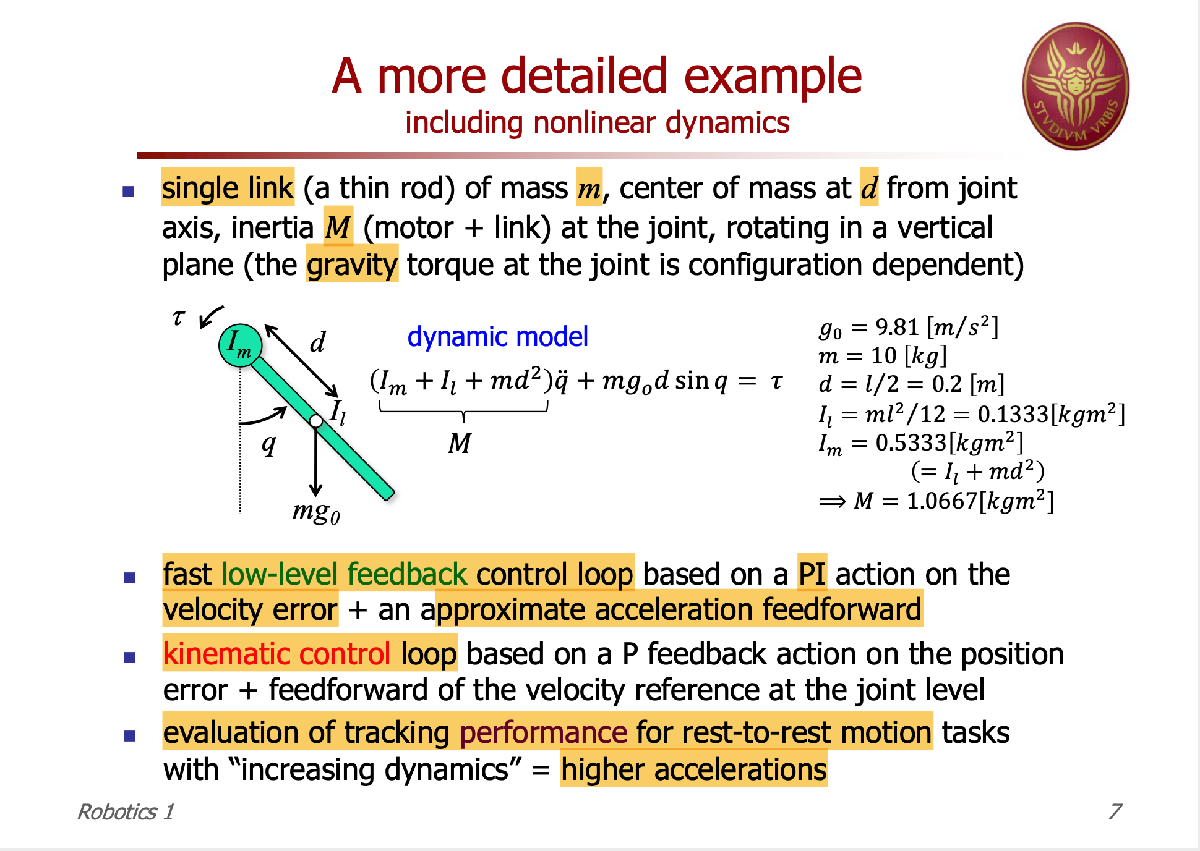

g = 9.81 %m/s^2

g = 9.8100

m = 10 %Kg

m = 10

l = 0.4 %m

l = 0.4000

d = l/2 %m

d = 0.2000

I_l = m*l^2/12 %Kg*m^2

I_l = 0.1333

I_m = I_l + m*d^2 %Kg*m^2

I_m = 0.5333

M = I_l+I_m+m*d^2 %Kg*m^2

M = 1.0667

tau0=0

tau0 = 0

tau_max=100 %Nm

tau_max = 100

w0=0

w0 = 0

q0=0

q0 = 0

qf=pi/2

qf = 1.5708

fake_der = 1

fake_der = 1

Kff = 50

Kff = 50

K = 50

K = 50

DT = 1

DT = 1

%simOut = sim('CONTROL_1R',DT);

# KINEMATIC CONTROL AT JOINT MOTION

syms alpha1 a1 d1 q1
syms alpha2 a2 d2 q2
syms alpha3 a3 d3 q3
syms alpha4 a4 d4 q4
syms alpha5 a5 d5 q5
syms alpha6 a6 d6 q6

% q1=sym(str2sym('q(1)'))
% q2=sym(str2sym('q(2)'))
% q3=sym(str2sym('q(3)'))
% q4=sym(str2sym('q(4)'))
% q5=sym(str2sym('q(5)'))
% q6=sym(str2sym('q(6)'))

disp('ANTROPOMORPHIC ARM WITH SPHERICAL WRIST')

ANTROPOMORPHIC ARM WITH SPHERICAL WRIST



DH_table_arm = ...
    [sym(pi/2)  0   0   q1;
        0       a2  0   q2;
    sym(pi/2)  a3   0   q3];

DH_table_wrist = ...
   [sym(-pi/2)  0  d4  q4;
    sym(pi/2)   0  0   q5;
       0        0  0   q6];
%d6=0 to have simpler expression
DH_table_ = [DH_table_arm; DH_table_wrist];

SR_ROBO.showDHTable(DH_table_)

    joint_i     alpha_i      a_i       d_i      theta_i
    _______    _________    ______    ______    _______

       1       {'pi/2' }    {'0' }    {'0' }    {'q1'} 
       2       {'0'    }    {'a2'}    {'0' }    {'q2'} 
       3       {'pi/2' }    {'a3'}    {'0' }    {'q3'} 
       4       {'-pi/2'}    {'0' }    {'d4'}    {'q4'} 
       5       {'pi/2' }    {'0' }    {'0' }    {'q5'} 
       6       {'0'    }    {'0' }    {'0' }    {'q6'} 




[T_sym, A_list_sym, type] = SR_ROBO.dh2dk(DH_table_,true);

A1 =


$$\left(\begin{array}{cccc} \cos\left(q_{1}\right) & 0 & \sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & 0 & -\cos\left(q_{1}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A2 =


$$\left(\begin{array}{cccc} \cos\left(q_{2}\right) & -\sin\left(q_{2}\right) & 0 & a_{2}\,\cos\left(q_{2}\right)\\ \sin\left(q_{2}\right) & \cos\left(q_{2}\right) & 0 & a_{2}\,\sin\left(q_{2}\right)\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A3 =


$$\left(\begin{array}{cccc} \cos\left(q_{3}\right) & 0 & \sin\left(q_{3}\right) & a_{3}\,\cos\left(q_{3}\right)\\ \sin\left(q_{3}\right) & 0 & -\cos\left(q_{3}\right) & a_{3}\,\sin\left(q_{3}\right)\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A4 =


$$\left(\begin{array}{cccc} \cos\left(q_{4}\right) & 0 & -\sin\left(q_{4}\right) & 0\\ \sin\left(q_{4}\right) & 0 & \cos\left(q_{4}\right) & 0\\ 0 & -1 & 0 & d_{4}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A5 =


$$\left(\begin{array}{cccc} \cos\left(q_{5}\right) & 0 & \sin\left(q_{5}\right) & 0\\ \sin\left(q_{5}\right) & 0 & -\cos\left(q_{5}\right) & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

A6 =


$$\left(\begin{array}{cccc} \cos\left(q_{6}\right) & -\sin\left(q_{6}\right) & 0 & 0\\ \sin\left(q_{6}\right) & \cos\left(q_{6}\right) & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

T06 =


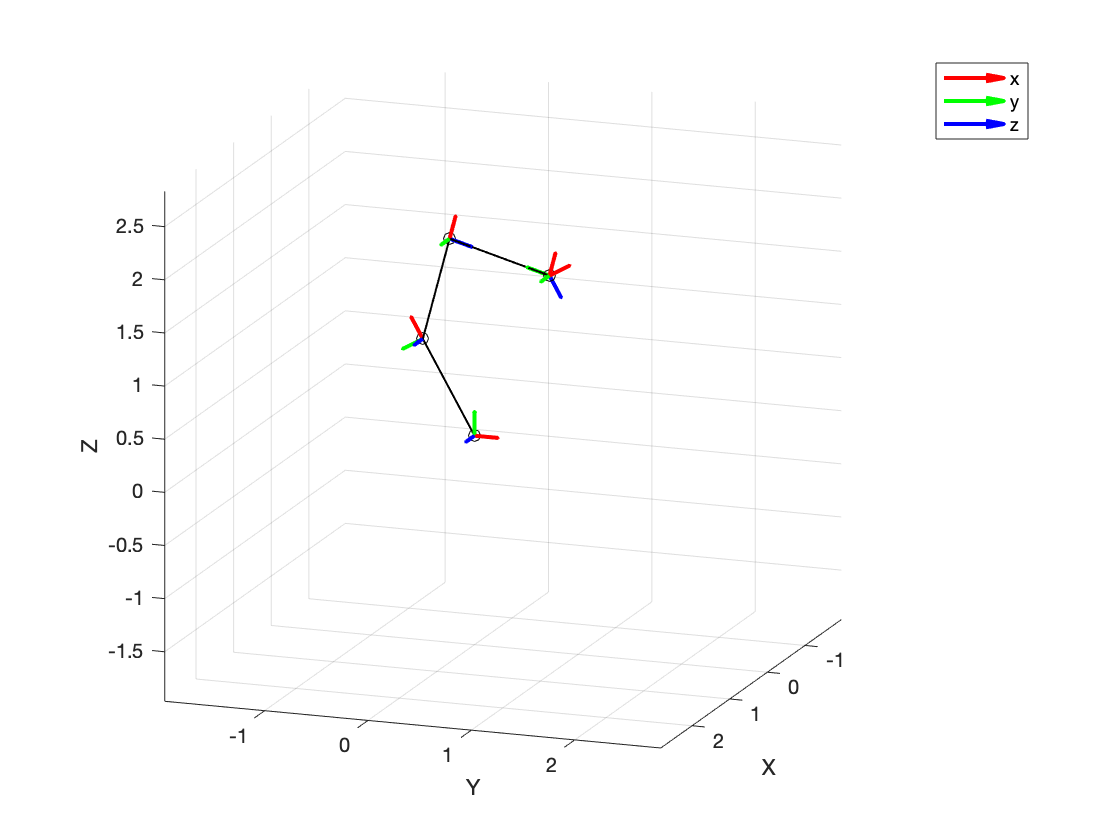


variables = { a2, a3, d4, q1, q2, q3, q4, q5, q6};

configuration = { 1, 1, 1, pi/2, 2*pi/3, -pi/4, 0, -pi/4, 0}; % singular configuration {q2,q3},[pi/2 pi/2]

A_list = cell(1,size(A_list_sym,1));

for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},variables,configuration));
end

% PLOT ROBOT
SR_ROBO.draw(A_list,false);

% JACOBIAN
only_joint_variables = {1, 1, 1, q1, q2, q3, q4, q5, q6};

F_sym = subs(T_sym(1:3,4),variables,only_joint_variables)

$$F\_sym = \left(\begin{array}{c} \cos\left(q_{1}\right)\,\left(\cos\left(q_{2}+q_{3}\right)+\sin\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right)\right)\\ \sin\left(q_{1}\right)\,\left(\cos\left(q_{2}+q_{3}\right)+\sin\left(q_{2}+q_{3}\right)+\cos\left(q_{2}\right)\right)\\ \sin\left(q_{2}+q_{3}\right)-\cos\left(q_{2}+q_{3}\right)+\sin\left(q_{2}\right) \end{array}\right)$$


R_sym = subs(T_sym(1:3,1:3),variables,only_joint_variables)


J = simplify(SR_ROBO.geometric_jacobian(subs(DH_table_,variables,only_joint_variables)))


J_r = simplify(J(1:3,1:3))

$$J\_r = \begin{array}{l} \left(\begin{array}{ccc} -\sin\left(q_{1}\right)\,\sigma_{1} & -\cos\left(q_{1}\right)\,\sigma_{2} & \sqrt{2}\,\sigma_{3}\,\cos\left(q_{1}\right)\\ \cos\left(q_{1}\right)\,\sigma_{1} & -\sin\left(q_{1}\right)\,\sigma_{2} & \sqrt{2}\,\sigma_{3}\,\sin\left(q_{1}\right)\\ 0 & \sigma_{1} & \sqrt{2}\,\sin\left(q_{2}+q_{3}+\frac{\pi }{4}\right) \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{2}\right)+\sqrt{2}\,\sin\left(q_{2}+q_{3}+\frac{\pi }{4}\right)\\ \sigma_{2}=\sin\left(q_{2}\right)-\sqrt{2}\,\sigma_{3}\\ \sigma_{3}=\cos\left(q_{2}+q_{3}+\frac{\pi }{4}\right) \end{array}$$


J_ee = simplify(J(4:6,1:6));

J_inv_r = simplify(inv(J_r))

$$J\_inv\_r = \begin{array}{l} \left(\begin{array}{ccc} -\frac{\sqrt{2}\,\sin\left(q_{1}\right)}{\sigma_{3}} & \frac{\sqrt{2}\,\cos\left(q_{1}\right)}{\sigma_{3}} & 0\\ -\frac{\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{1}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{2}\right)-\cos\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)}{\sigma_{2}} & -\frac{\cos\left(q_{2}\right)\,\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)-\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{2}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{3}\right)+\cos\left(q_{3}\right)\,\sin\left(q_{1}\right)\,\sin\left(q_{2}\right)}{\sigma_{2}} & \frac{\cos\left(\sigma_{5}\right)}{\sigma_{1}}\\ \frac{\sqrt{2}\,\cos\left(q_{1}\right)\,\sigma_{4}}{2\,\sigma_{1}} & \frac{\sqrt{2}\,\sin\left(q_{1}\right)\,\sigma_{4}}{2\,\sigma_{1}} & \frac{\sqrt{2}\,\left(\sin\left(q_{2}\right)-\sqrt{2}\,\cos\left(\sigma_{5}\right)\right)}{2\,\sigma_{1}} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(q_{3}+\frac{\pi }{4}\right)\\ \sigma_{2}=\cos\left(q_{3}\right)-\sin\left(q_{3}\right)\\ \sigma_{3}=2\,\sin\left(\sigma_{5}\right)+\sqrt{2}\,\cos\left(q_{2}\right)\\ \sigma_{4}=\cos\left(q_{2}\right)+\sqrt{2}\,\sin\left(\sigma_{5}\right)\\ \sigma_{5}=q_{2}+q_{3}+\frac{\pi }{4} \end{array}$$


%J_psed_ee = simplify(SR_ROBO.pseudo_inverse_jacobian(J_ee)) %run time

% TIME
start_time=0;
end_time=4;
T = end_time-start_time;

time_step=0.01;
num_steps=T/time_step;
time_vector = time_step * [start_time:num_steps]';

sigma_vector = time_vector/T;

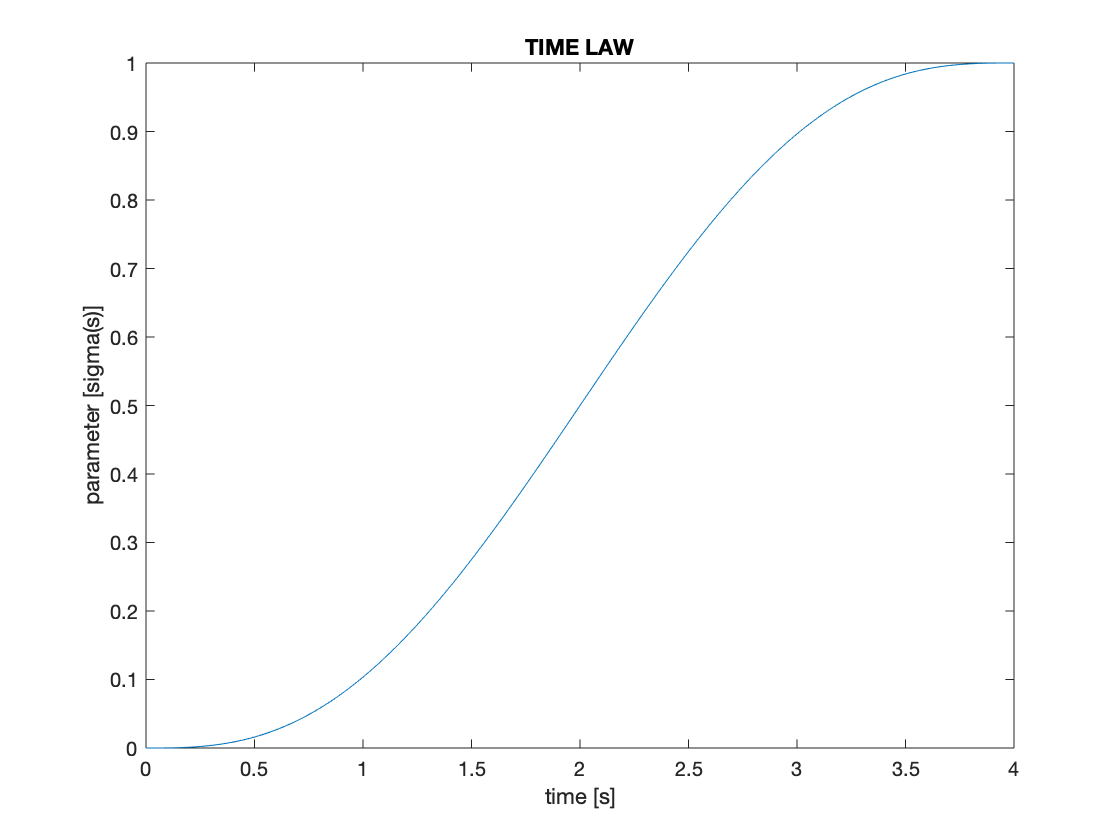

% TIME LAW
for t=1:length(time_vector)
    sigma_vector(t) = SR_ROBO.ptp_quintic(0,1,0*T,0*T,0*T^2,0*T^2,time_vector(t)/T);
end
figure
clf;
plot(time_vector,sigma_vector)
xlabel('time [s]');
ylabel('parameter [sigma(s)]');
title('TIME LAW')

% TRAJECTORY

% CIRCULAR
[A, B, C] = deal([0.5 1 0]', [1 0.5 0]', [1.5 1 0.25]');
[~,c,r] = SR_ROBO.circular_3_points(A,B,C,0)

c =     1.0000
    1.0000
    0.1250


r = 0.5154


% CUBIC SPLINE
% KNOT: TIME [0,1] - POSITION - VELOCITY
% knots_x = {{0, 0, 0 * T}, ...
%     {0.125, 0, 'none'}, ... 
%     {0.25, 1, 'none'}, ... 
%     {0.375, 1, 'none'}, ...
%     {0.5, 0, 'none'}, ... 
%     {0.625, 0, 'none'}, ... 
%     {0.750, 1, 'none'}, ... 
%     {0.875, 1, 'none'}, ... 
%     {1, 0, 0 * T}};
% 
% knots_y = {{0, 0, 0 * T}, ...
%     {0.125, 1, 'none'}, ... 
%     {0.25, 1, 'none'}, ... 
%     {0.375, 1, 'none'}, ...
%     {0.5, 1, 'none'}, ... 
%     {0.625, 0, 'none'}, ... 
%     {0.750, 0, 'none'}, ... 
%     {0.875, 0, 'none'}, ... 
%     {1, 0, 0 * T}};
% 
% knots_z = {{0, 0, 0 * T}, ...
%     {0.125, 0, 'none'}, ... 
%     {0.25, 0, 'none'}, ... 
%     {0.375, 1, 'none'}, ...
%     {0.5, 1, 'none'}, ... 
%     {0.625, 1, 'none'}, ... 
%     {0.750, 1, 'none'}, ... 
%     {0.875, 0, 'none'}, ... 
%     {1, 0, 0 * T}};
% 
% for i=1:length(knots_x)
%     knots_x{i}{2}=knots_x{i}{2}+0.5;
%     knots_y{i}{2}=knots_y{i}{2}+0.5;
%     knots_z{i}{2}=knots_z{i}{2}+0.5;
% end
% 
% coeff_x = SR_ROBO.cubic_spline_coefficients(knots_x);
% coeff_y = SR_ROBO.cubic_spline_coefficients(knots_y);
% coeff_z = SR_ROBO.cubic_spline_coefficients(knots_z);

trajectory = [zeros(length(time_vector),3)];

max_distance=0;
for s=1:length(sigma_vector)
    [trajectory(s,:),~,~] = SR_ROBO.circular_3_points(A,B,C,sigma_vector(s));
%     trajectory(s,:) = [SR_ROBO.cubic_spline(coeff_x,knots_x,sigma_vector(s)) ...
%         SR_ROBO.cubic_spline(coeff_y,knots_z,sigma_vector(s)) ...
%         SR_ROBO.cubic_spline(coeff_z,knots_z,sigma_vector(s))];
    if norm(trajectory(s,:))>max_distance
        max_distance =norm(trajectory(s,:));
        assert(max_distance<3, 'max distance should be lower that workspace')
    end
end
max_distance

max_distance = 1.9232

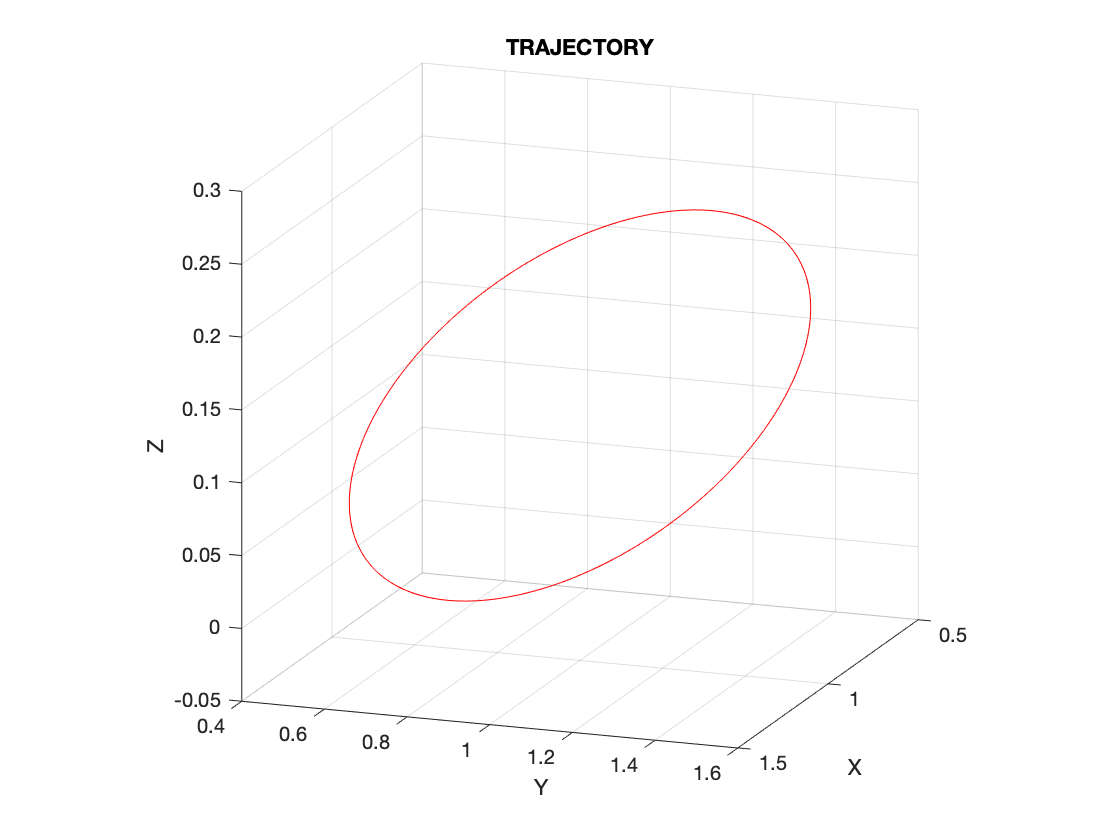


clf;
hold on
plot3(trajectory(:,1),trajectory(:,2),trajectory(:,3), 'r')
title('TRAJECTORY')
xlabel('X');
ylabel('Y');
zlabel('Z');
view([110 15]);
grid on
pbaspect([1 1 1]);
hold off

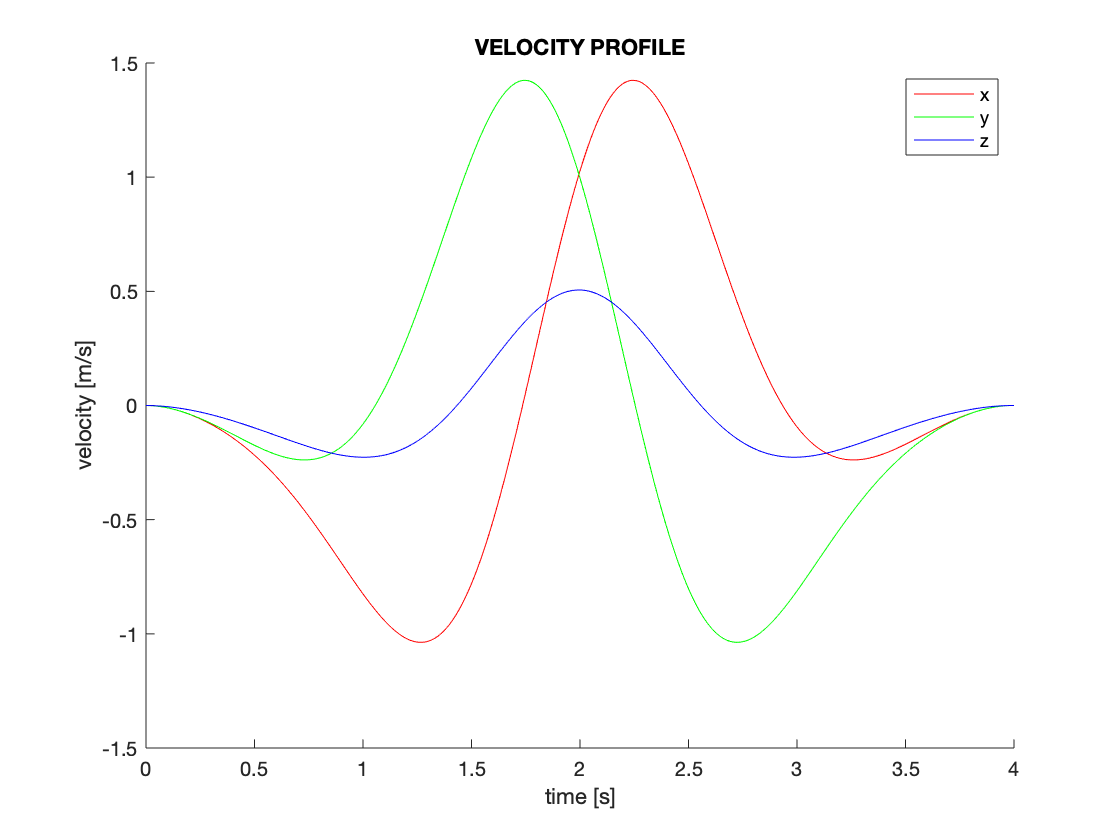

% VELOCITY
velocity = trajectory;
for t=1:length(time_vector)-1
    velocity(t,:) = (trajectory(t+1,:)-trajectory(t,:))/time_step;
end
velocity(length(time_vector),:) = velocity(length(time_vector)-1,:);

clf;
hold on
plot(time_vector,velocity(:,1), 'r')
plot(time_vector,velocity(:,2), 'g')
plot(time_vector,velocity(:,3), 'b')
legend('x','y','z')
title('VELOCITY PROFILE')
xlabel('time [s]');
ylabel('velocity [m/s]');
hold off

% INVERSE KINEMTATIC
q0=[pi/2 pi/2 -pi/2]'

q0 =     1.5708
    1.5708
   -1.5708


pd0 = trajectory(1,:)'

pd0 =     1.3644
    0.6356
    0.1250


qd0 = SR_ROBO.grad(F_sym,q0,pd0,0.5)'; % GRADIENT

max iter exceeded
iter : 50 
error : 0.000950 
q_opt : 
    0.4359
    1.2153
   -1.0426



%qd0 = SR_ROBO.newton(F_sym,q0,pd0); % NEWTON

Rd0 = [0 0 1;
    0 -1 0;
    1 0 0];
Rdf = [1 0 0;
    0 0 1;
    0 -1 0];

R_a = Rd0;
 
R_b = Rdf;

[~,~,axis,theta_ab] = SR_ROBO.axis_angle_trajectory(R_a,R_b,0)

axis =     0.5774
   -0.5774
    0.5774


theta_ab = 2.0944

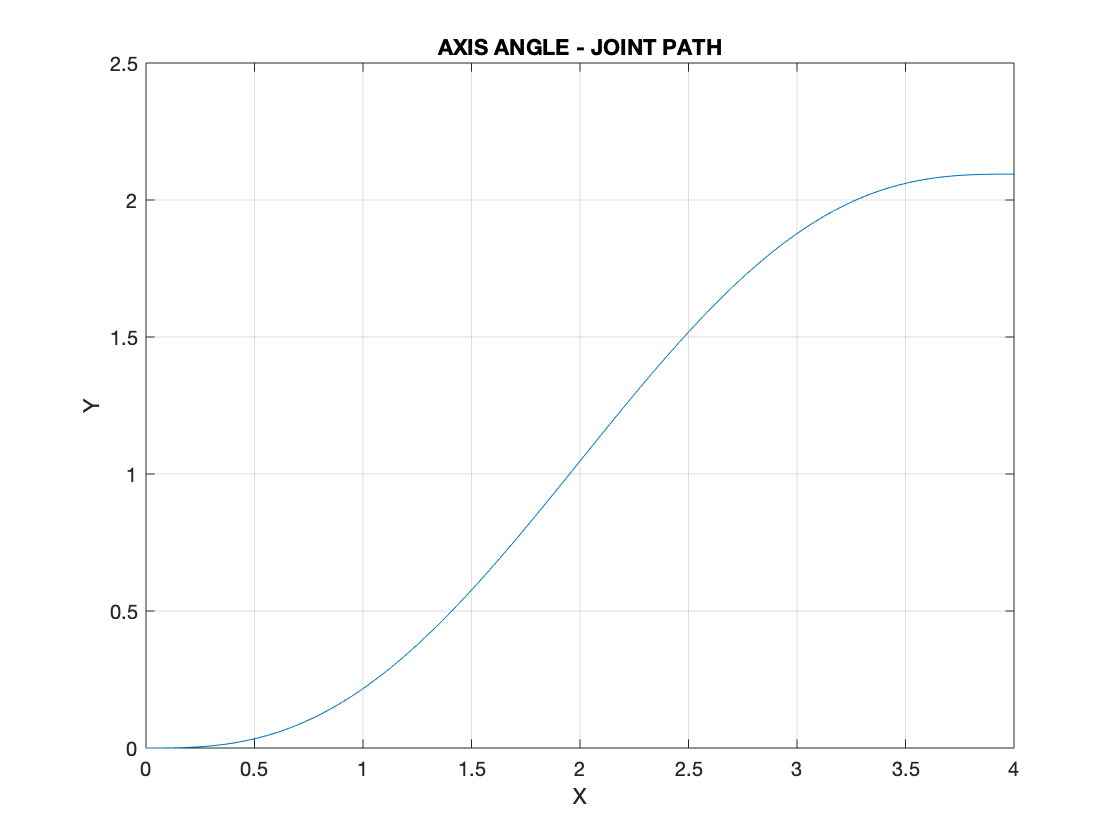


%roration_traj = zeros(3,3,length(time_vector));
theta_traj = zeros(length(time_vector),1);
%roration_traj(:,:,s)
% TRAJECTORY
for s=1:length(sigma_vector)
    [~,theta_traj(s),~,~] = SR_ROBO.axis_angle_trajectory(R_a,R_b,sigma_vector(s));
end
%theta_traj(s,:) = SR_ROBO.R_zyz_inv(roration_traj(:,:,s),1);
figure 
plot(time_vector,theta_traj)
title('AXIS ANGLE - JOINT PATH')
xlabel('X');
ylabel('Y');
grid on


%SR_ROBO.draw_axis_angle_trajectory(roration_traj);

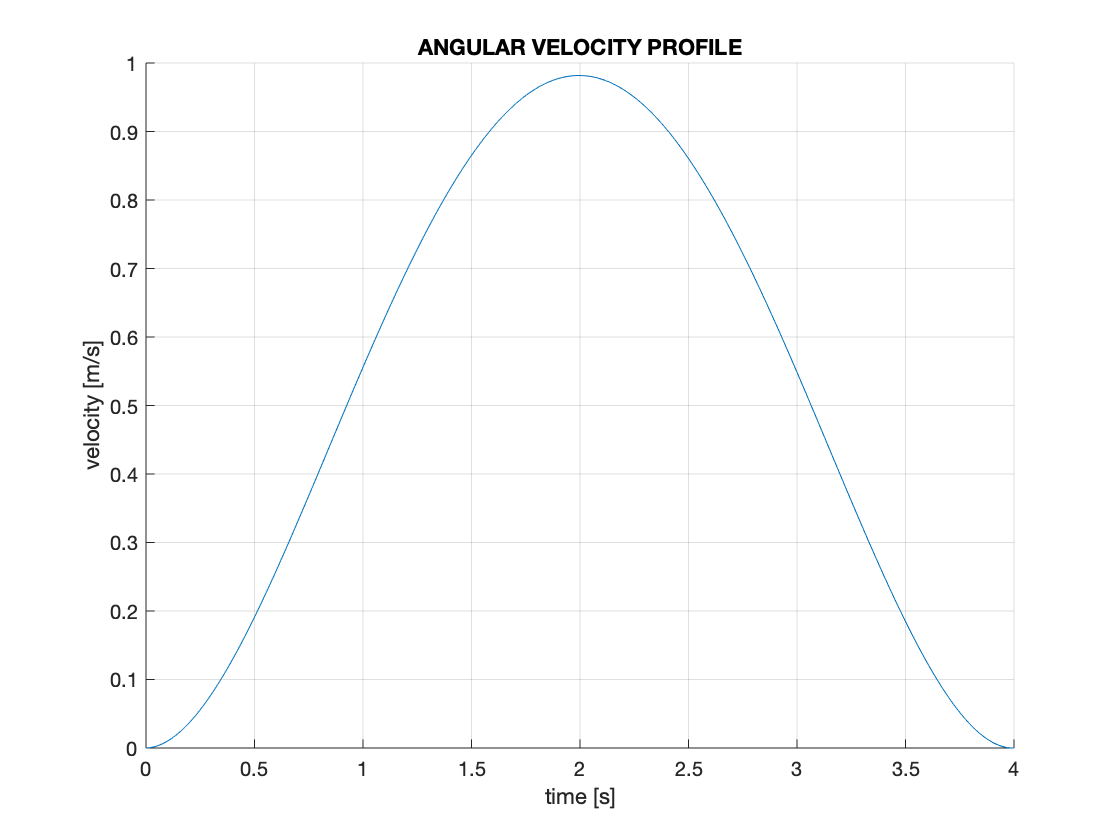

% ANGULAR VELOCITY
theta_velocity = theta_traj;
for t=1:length(time_vector)-1
    theta_velocity(t) = (theta_traj(t+1)-theta_traj(t))/time_step;
end
theta_velocity(length(time_vector)) = theta_velocity(length(time_vector)-1);

clf;
hold on
plot(time_vector,theta_velocity(:))
title('ANGULAR VELOCITY PROFILE')
xlabel('time [s]');
ylabel('velocity [m/s]');
grid on
hold off

% INITIAL EE ORIENTATION
only_ee_variables = {1, 1, 1, 0, 0, 0, q4, q5, q6 };

R0 = simplify(subs(R_sym,variables,only_ee_variables));


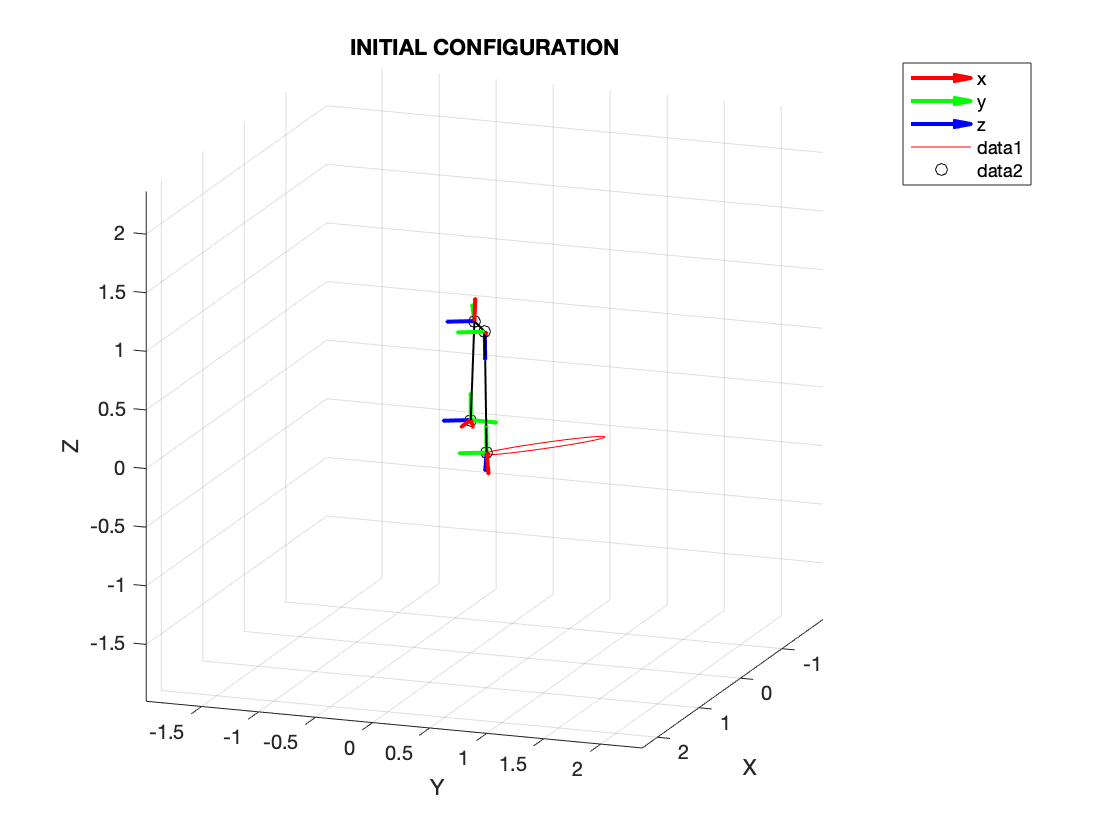

% SHOW INITIAL CONFIGURATION
clf;
variables = { a2, a3, d4, q1, q2, q3, q4, q5, q6};
configuration = { 1, 1, 1, qd0(1), qd0(2), qd0(3), 0, -pi/4, 0};

A_list = cell(1,size(A_list_sym,1));
for i=1: length(A_list_sym)
    A_list{i} = double(subs(A_list_sym{i},variables,configuration));
end
SR_ROBO.draw(A_list,false);

hold on
plot3(trajectory(:,1),trajectory(:,2),trajectory(:,3), 'r')
plot3(trajectory(1,1),trajectory(1,2),trajectory(1,3),'ko')
title('INITIAL CONFIGURATION')
hold off

% CONTROL
desired_vel.time = time_vector;
desired_vel.signals.values = velocity;
desired_vel.signals.dimensions = 3;

desired_theta.time = time_vector;
desired_theta.signals.values = theta_velocity;
desired_theta.signals.dimensions = 1;

K = [50 50 50];
K_theta = 50;
 % how to find best configuration according to mechanical limits?
q_max = [2*pi 2*pi 2*pi;
        -2*pi -2*pi -2*pi]

q_max =     6.2832    6.2832    6.2832
   -6.2832   -6.2832   -6.2832


q_dot_max = [100 100 100;
            -100 -100 -100];
q0=qd0

q0 =     0.4359    1.2153   -1.0426


theta_dot_0 = theta_velocity(1)

theta_dot_0 = 3.2602e-05

theta_0 = theta_traj(1)

theta_0 = 0

axis

axis =     0.5774
   -0.5774
    0.5774


% SIMULINK
simOut = sim('CONTROL_JOINT',T);

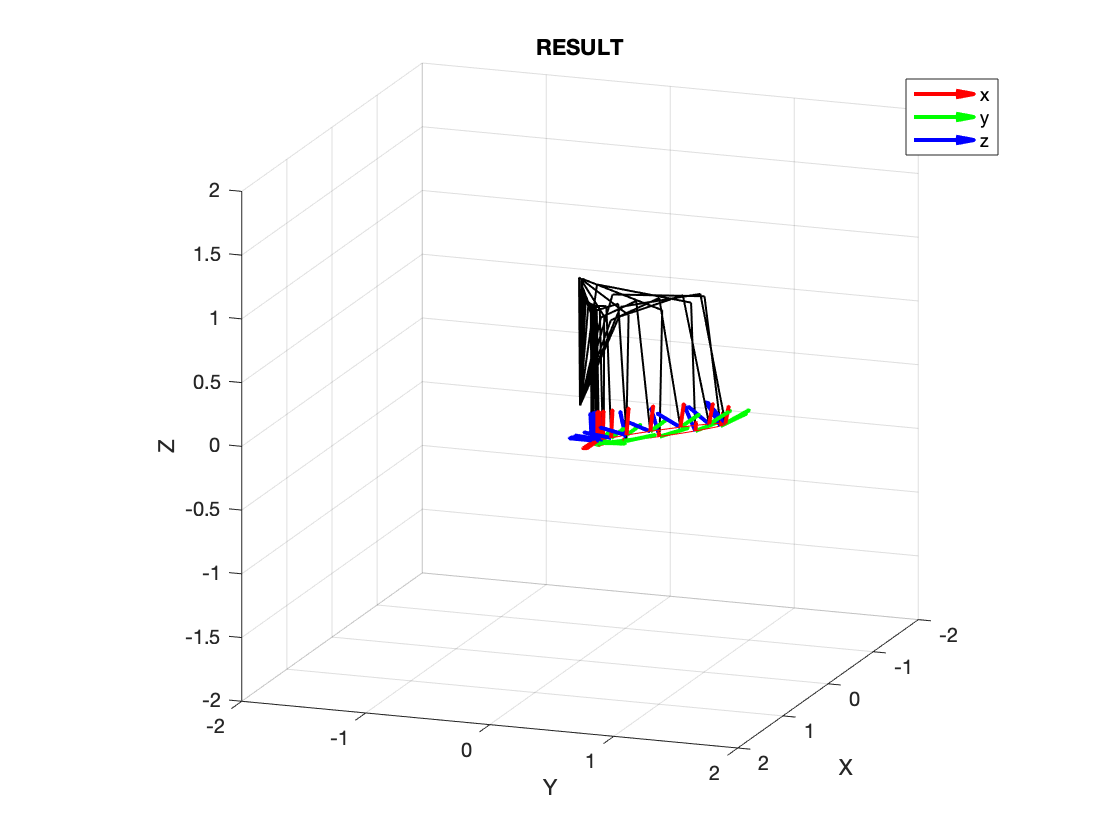

clf
hold on
% PLOT TRAJECTORY
plot3(trajectory(:,1),trajectory(:,2),trajectory(:,3), 'r')
plot3(trajectory(1,1),trajectory(1,2),trajectory(1,3),'go')
title('RESULT')

% PLOT RESULT
radius = 2;
for i=1:length(time_vector)
    if mod(i-1,20)==0
        q = simOut.control_joint_task_angles.Data(i,:);
        q_e = simOut.control_joint_task_angles_ee.Data(i,:);
        configuration = { 1, 1, 1, q(1), q(2), q(3), q_e(1), q_e(2), q_e(3)};
        SR_ROBO.draw_clean(A_list_sym,variables,configuration,radius,false);
        xlabel('X');
        ylabel('Y');
        zlabel('Z');
        view([110 15]);
        grid on
        pbaspect([1 1 1]);
        xlim([-2 2])
        ylim([-2 2])
        zlim([-2 2])
        drawnow
    end
end
hold off